# Eigenface

clear all, close all, clc
load allFaces.mat

We use the first 36 people as training data

trainingFaces = faces(:,1:sum(nfaces(1:36)));
avgFace = mean(trainingFaces,2);
A = trainingFaces-avgFace*ones(1,size(trainingFaces,2));
tic
[U,S,V] = svd(A,'econ');
toc

set(groot,'DefaultFigureColormap',gray);
ratio = [m n 1];

figure;
imagesc(reshape(avgFace,n,m)), axis off, pbaspect(ratio)
title("Average Face")

EigenFaces = zeros(n*4,m*4);
count = 1;
for i=1:4
    for j =1:4
        EigenFaces(1+(i-1)*n:i*n,1+(j-1)*m:j*m) ... % plot the first 16 eigenfaces
            = reshape(U(:,count),n,m);
        count = count + 1;
    end
end

figure;
imagesc(EigenFaces), axis off, pbaspect(ratio)
title("First 16 Eigenfaces")

## Reconstruction of a face that is not in the training set

myFace = zeros(n*m,20);

for i=1:20
    myFaces = imread(sprintf(['my_face_', num2str(i), '.pgm']));
    myFace(:,i) = reshape(myFaces,n*m,1);
end

myFaces = zeros(n*4,m*5);
count = 1;

for i=1:4
    for j =1:5
        myFaces(1+(i-1)*n:i*n,1+(j-1)*m:j*m) ...% plot the first 64 eigenfaces
            = reshape(myFace(:,count),n,m);
        count = count + 1;
    end
end

figure;
imagesc(myFaces), pbaspect([168*5 192*4 1]), axis off;
title("My Faces")

myFaceMS = myFace(:,1) - avgFace;

The top left face will be reconstructed.

### 1) Reconstruction with gradually increasing r

figure;
tic
for r=5:5:1250
    reconFace = avgFace + (U(:,1:r)*(U(:,1:r)'*myFaceMS));
    imagesc(reshape(reconFace,n,m)), pbaspect(ratio)
    title(['r = ',num2str(r,'%d')]);
    pause(0.001)
end
toc

### 2) Reconstruction result comparision by increading r

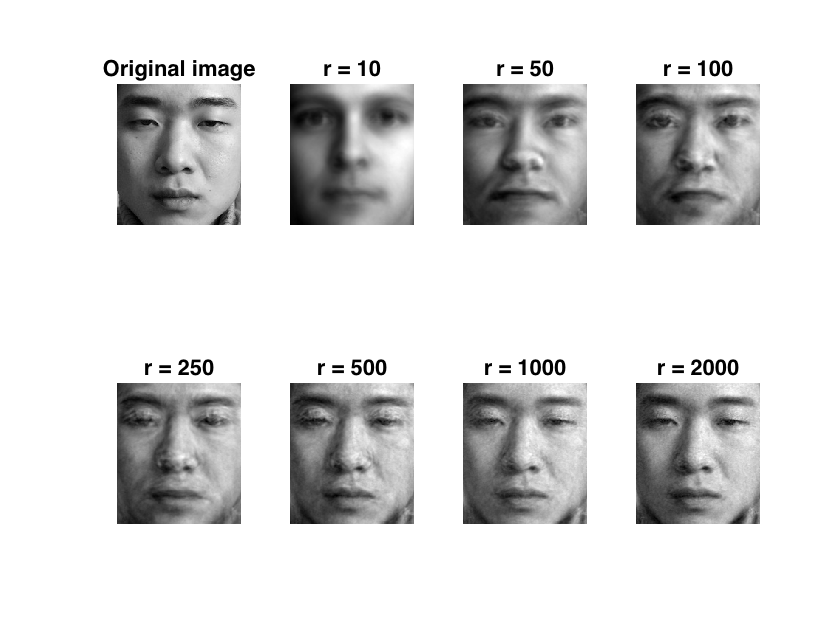

figure;

i = 1;
subplot(2,4,1)
imagesc(reshape(myFace(:,1),n,m)), axis off, pbaspect(ratio);

title('Original image');
for r = [10 50 100 250 500 1000 2000]
    i = i + 1;
    subplot(2,4,i)
    reconFace = avgFace + (U(:,1:r) * (U(:,1:r)' * myFaceMS));
    imagesc(reshape(reconFace,n,m)), axis off, pbaspect(ratio);
    title(['r = ',num2str(r,'%d')]);
end

## Face recognition of two people that are not in the training set

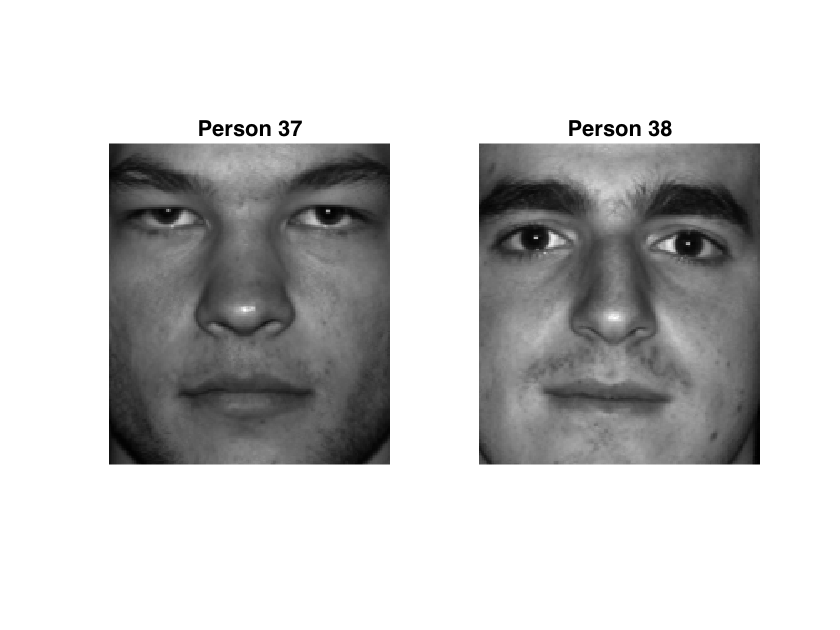

P1num = 37;  % person number 37
P2num = 38;  % person number 38
P1 = faces(:,1+sum(nfaces(1:P1num-1)):sum(nfaces(1:P1num)));
P2 = faces(:,1+sum(nfaces(1:P2num-1)):sum(nfaces(1:P2num)));
P1ms = P1 - avgFace*ones(1,size(P1,2)); % subtract mean vector
P2ms = P2 - avgFace*ones(1,size(P2,2));

figure;
subplot(1,2,1), imagesc(reshape(P1(:,1),n,m)); colormap gray, axis off
title(['Person ',num2str(P1num)])
pbaspect ([168 192 1])
subplot(1,2,2), imagesc(reshape(P2(:,1),n,m)); colormap gray, axis off
title(['Person ',num2str(P2num)])
pbaspect ([168 192 1])

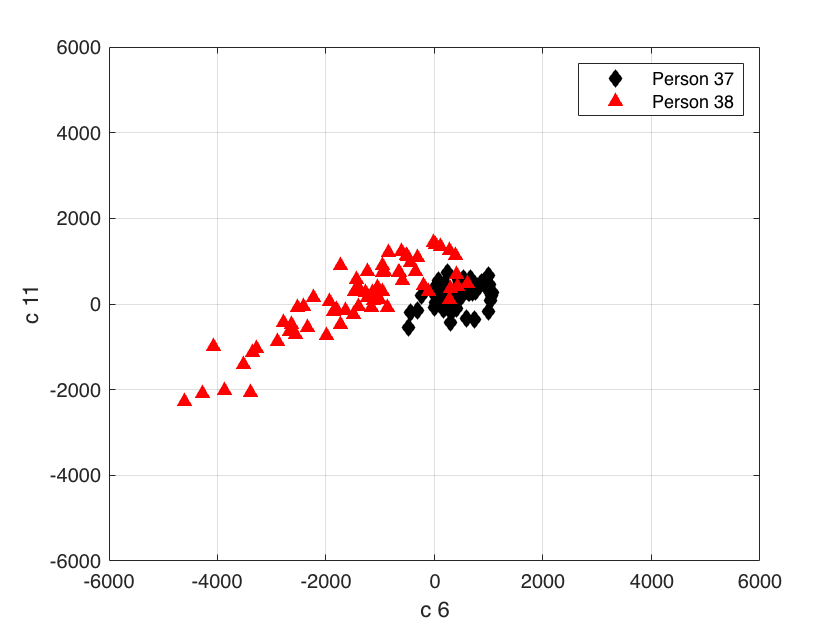


% project onto eigenfaces
PCAmode = [6 11];

PCACoordP1 = U(:,PCAmode)'*P1ms;
PCACoordP2 = U(:,PCAmode)'*P2ms;

figure;
plot(PCACoordP1(1,:),PCACoordP1(2,:),'kd','MarkerFaceColor','k')
axis ([-6000 6000 -6000 6000]), hold on, grid on
plot(PCACoordP2(1,:),PCACoordP2(2,:),'r^','MarkerFaceColor','r')
legend(['Person ',num2str(P1num)], ['Person ',num2str(P2num)])

xlabel(['c ' num2str(PCAmode(1))]) 
ylabel(['c ' num2str(PCAmode(2))])

Face recognition can be done by clustering if the coordinates are well separated 